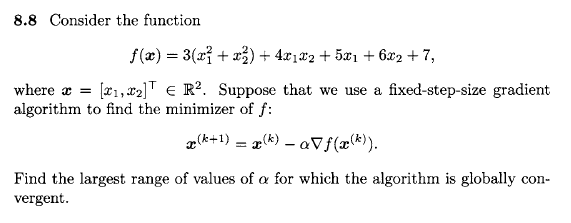

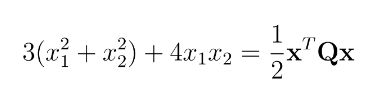

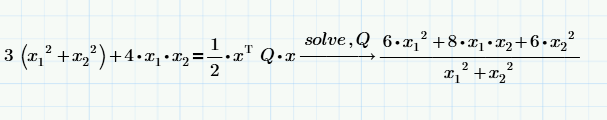

You can then solve for Q and get that (Not very nice in Mathcad :/)


Q = [6,4;4,6]

Q =      6     4
     4     6



[V,D] = eig(Q)

V =    -0.7071    0.7071
    0.7071    0.7071


D =     2.0000         0
         0   10.0000


amax = 2/max(D,[],'all') % Gives largets eigenvalue

amax = 0.2000

% therefore alpha must be 0<a<aMax % 0 < a < 2/lambdaMax(Q)

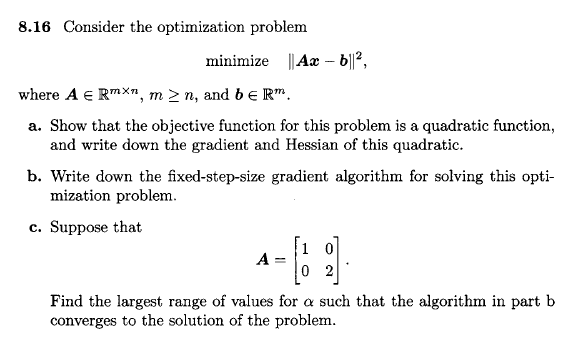

a) Show that the objective function for this problem is a quadratic function, and write down the gradient and hessian of this quadratic


$$f\left(x\right)=||\mathrm{Ax}-b||^2$$



$$f\left(x\right)={\left(\mathrm{Ax}-b\right)}^T \left(\mathrm{Ax}-b\right)$$



$$f\left(x\right)={\left(A^T x^T -b^T \right)} \left(\mathrm{Ax}-b\right)$$



$$f\left(x\right)=A\cdot A^T \cdot x\cdot x^T +b\cdot b^T -A\cdot b^T \cdot x-A^T \cdot b\cdot x^T$$



$$f\left(x\right)=x^T \left(A^T A\right)x-2{\left(A^T b\right)}^T x+b^T b$$


And this is a quadratic function which we can find the gradient of

gradient:


$$\Delta f\left(x\right)=2\left(A^T A\right)x-2\left(A^T b\right)$$


hessian:


$$F\left(x\right)=2\left(A^T A\right)$$


b) Write down the fixed-step-size gradient algoritm for solving this optimization problem


$$\begin{array}{l}
x^{\left(k+1\right)} =x^{\left(k\right)} -\alpha \left(2\left(A^T A\right)x^{\left(k\right)} -2\left(A^T b\right)\right)\\
x^{\left(k+1\right)} =x^{\left(k\right)} -2\alpha A^T \left({\mathrm{Ax}}^{\left(k\right)} -b\right)
\end{array}$$


c) The largest range of values for alpha, such that the algoritm in part b converges to the solution of the problem is given by

$A=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right\rbrack$ From object description

A =  [1,0;0,2];
Q = (2*A*transpose(A));
alphaMax = 2/max(Q,[],'all')

alphaMax = 0.2500


$$\lambda_{\max } \left(Q\right)=\lambda_{\max } \left(2\cdot A\cdot A^T \right)=\frac{1}{4}$$


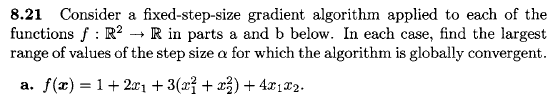

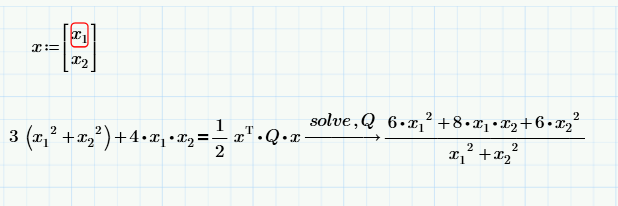


$$Q=\left\lbrack \begin{array}{cc}
6 & 4\\
4 & 6
\end{array}\right\rbrack$$


Q = [6,4;4,6];
[V,D] = eig(Q)

V =    -0.7071    0.7071
    0.7071    0.7071


D =     2.0000         0
         0   10.0000


amax = 2/max(D,[],'all')

amax = 0.2000

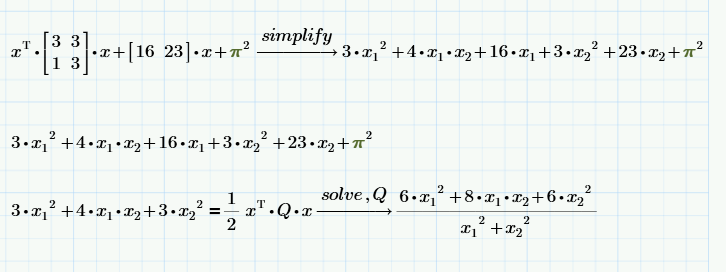

Q = [6,4;4,6];
[V,D] = eig(Q)

V =    -0.7071    0.7071
    0.7071    0.7071


D =     2.0000         0
         0   10.0000


amax = 2/max(D,[],'all')

amax = 0.2000